## One Dimensional Drag Example

## Simulation 1

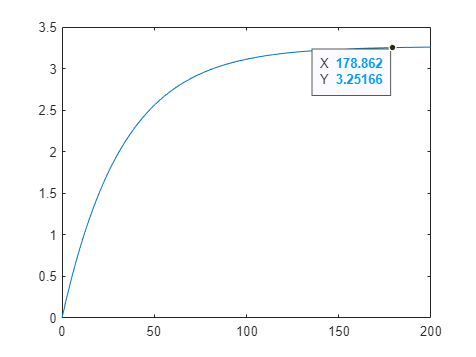

clc
clear

C_D= 0.5;
p = 1.225; %Kg/m^3
m = 10; %Kg
init_vel = 0; %m/s
F_T = 1; %N
y(1) = 0; %inital value
h = 0.001; %step size
end_time = 200;
N = end_time/h;  %number of steps
b = drag_consts(C_D, p);

for n=1:N
    y(n+1) = y(n)+h*df(y(n), F_T, b, m);
    x(n+1) = n * h;
end

plot(x, y)

function res = df(v, F_T, b, m)
    res = (F_T - b * v)/m;
end

function res = drag_consts(C_D, p)
    res = 1/2 * C_D * p;
end